L1x = 100;	    % duree d'observation du signal d'entree (en s)
fe = 1;		    % frequence d'echantillonnage (Hz)
Te = 1/fe;		% periode d'echantillonnage
N1x = L1x/Te;	% nombre de points du signal x
kx = 0:N1x;	    % vecteur des indices temporels  
tx= kx*Te;		% vecteur des instants d'echantillonnage

## 1. Reponse impulsionnelle h d'un filtre gaussien

mu_h=15*Te;
% la largeur de la reponse impulsionnelle va rendre le probleme plus ou moins difficile
sigma_h=1*Te;
tt=(0:Te:30*Te);
h=(1/(sigma_h*sqrt(2*pi)))*exp(-(((tt-mu_h)/(sqrt(2)*sigma_h)).*((tt-mu_h)/(sqrt(2)*sigma_h))));
figure(1);
subplot(2,3,2)
plot(tt,h)
xlabel('temps (s)'); ylabel('amplitude'); title('Reponse impulsionnelle h(t)');

2. Signal x

k1 = 0:N1x/2-1;
t1 = k1*Te;
x1 = t1/(L1x/2); 
k2 = N1x/2:N1x;  % modif  N1x-1 => N1x
t2 = k2*Te;
x2 = (-t2 + L1x)/(L1x/2);
x = [x1 x2];
subplot(2,3,1)
plot(tx,x);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal entree x(t)');

2.1 Approche « naïve » par filtrage inverse

Partie 1 : simulation du problème direct

%1.Convolution
y_nb=conv(x,h);
N1=length(y_nb);
k=0:1:N1-1;
t=k*Te;
subplot(2,3,3)
plot(t,y_nb)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie non bruite y_{nb}(t)');
% 2. Simulation de l'operation de quantification
y = round(y_nb*2^10)/2^10;  %  q=1/2^10
subplot(2,3,6)
stairs(t,y);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie bruite y(t)');
% 3.Representation du bruit de quantification
w = y - y_nb;
subplot(2,3,5)
plot(t,w); 
xlabel('temps (s)'); ylabel('amplitude'); title('Bruit w(t)');
RSB=10*log10(y*y'/var(w)) % 

RSB = 87.4471

Partie 2 : interprétation fréquentielle de l’inversion

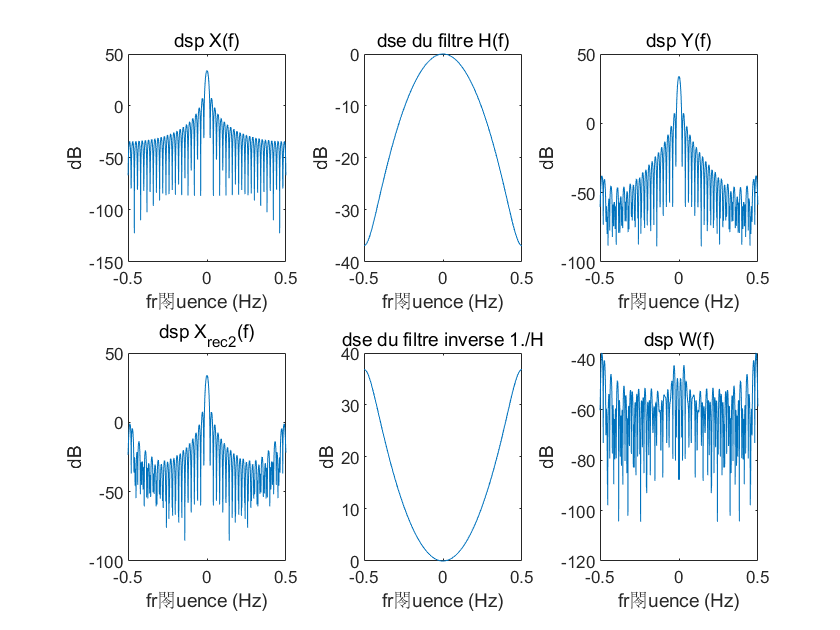

%1.Reponse en frequence du filtre
N=1024;
n = -N/2:N/2-1;
f = n*fe/N;
H = fft(h,N);
figure(2); subplot(2,3,2)
plot(f,fftshift(20*log10(abs(H))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre H(f)');
%2.  TFD X du signal d'entree, TFD Y du signal de sortie, TFD X_rec du signal reconstruit 
X = fft(x,N);
subplot(2,3,1)
plot(f,fftshift(20*log10(abs(X))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp X(f)');

Y = fft(y,N); % spectre du signal bruite
%Y=fft(y_nb,N); % spectre du signal non bruite
subplot(2,3,3)
plot(f,fftshift(20*log10(abs(Y))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp Y(f)');

%3. % Reponse en frequence du filtre inverse
Hinv = 1./H;
hinv = real(ifft(Hinv));%用快速傅里叶变换算法计算Y 的逆离散傅里叶变换。
subplot(2,3,5)
plot(f,fftshift(20*log10(abs(Hinv))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dse du filtre inverse 1./H');

%4.1 Reponse en frequence du bruit de quantification
W = fft(w,N);
subplot(2,3,6)
plot(f,fftshift(20*log10(abs(W))));
xlabel('frequence (Hz)'); ylabel('dB'); title('dsp W(f)');

%4.2 calcul du signal reconstruit par filtrage inverse
%
X_rec2 = Y./H;
x_rec2 = real(ifft(X_rec2));

Nrec2=length(x_rec2);
krec2=0:1:Nrec2-1;
trec2=krec2*Te;
figure(1);
subplot(2,3,4)
plot(trec2(1:length(x)),x_rec2(1:length(x)))
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit par filtrage inverse');

%5
figure(2)
subplot(2,3,3)
plot(f,fftshift(20*log10(abs(Y))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dsp Y(f)');
subplot(2,3,1)
plot(f,fftshift(20*log10(abs(X))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dsp X(f)');
subplot(2,3,2)
plot(f,fftshift(20*log10(abs(H))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dse du filtre H(f)');
subplot(2,3,6)
plot(f,fftshift(20*log10(abs(W))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dsp W(f)');
subplot(2,3,5)
plot(f,fftshift(20*log10(abs(Hinv))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dse du filtre inverse 1./H');
subplot(2,3,4)
plot(f,fftshift(20*log10(abs(X_rec2))));
xlabel('fr閝uence (Hz)'); ylabel('dB'); title('dsp X_{rec2}(f)');

6. En déduire l’interprétation fréquentielle du problème posé par l’opération de déconvolution.Il peut, à nouveau, être intéressant de faire varier le paramètre �h.

sigma<1 时候可以很好重建图像

## 第二部分： Déconvolution par régularisation quadratique l2

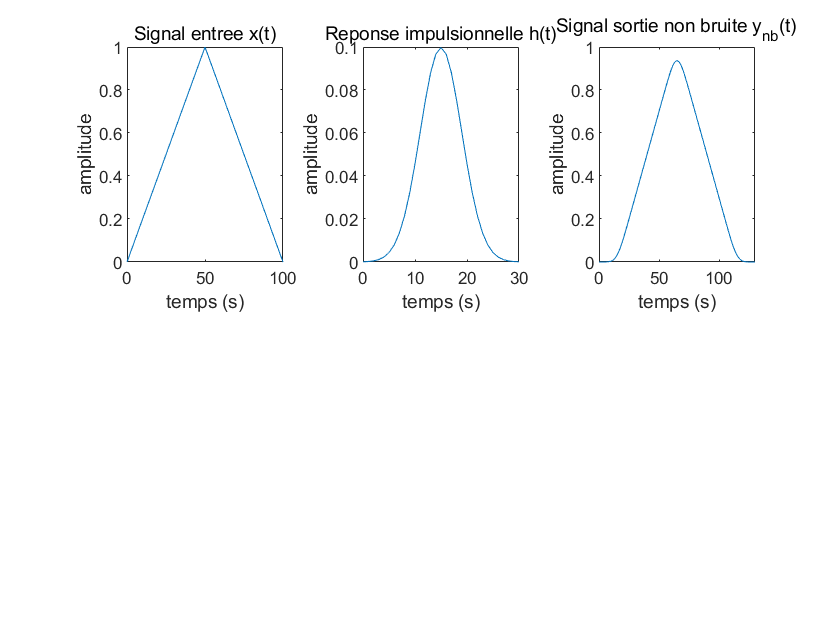

close all;
clear all;
L_x = 100;	    % dur閑 d'observation du signal d'entr閑
fe = 1;		    % fr閝uence d'閏hantillonage
Te = 1/fe;		% p閞iode d'閏hantillonage
N_x = L_x/Te;	% nombre de points du signal x
k_x = 0:N_x;	% index temporel
t_x= k_x*Te;    % base de temps
%**************************************************************************
% 1. Signal x
k1 = 0:N_x/2-1;
t1 = k1*Te;
x1 = t1/(L_x/2);
k2 = N_x/2:N_x;
t2 = k2*Te;
x2 = (-t2 + L_x)/(L_x/2);
x = [x1'; x2'];
subplot(2,3,1)
plot(t_x,x);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal entree x(t)');

% 2. Reponse impulsionnelle h de filtres lineaires gaussiens

mu_h=15*Te;
% test de plusieurs filtres gaussien ; la largeur de la r閜onse impulsionnelle va rendre le probl鑝e plus ou
% moins difficile
%**************************************************************************
N_sigma=30;
for sigma=1:N_sigma,
   sigma_h=sigma*Te;
   L_h=30*Te;
   t_h=(0:Te:L_h);
   N_h=length(t_h);
   h=(1/(sigma_h*sqrt(2*pi)))*exp(-(((t_h-mu_h)/(sqrt(2)*sigma_h)).*((t_h-mu_h)/(sqrt(2)*sigma_h))));
   % subplot(2,3,2)
   % plot(t_h,h)
   % xlabel('temps (s)'); ylabel('amplitude'); title('R閜onse impulsionnelle h(t)');
   
   %-----------------------------------------------------------------------
   % 3. Construction de la matrice H de convolution (Toeplitz)
   N_x=length(x);
   N_y = N_x + N_h -1;
   
   hcol_1 = zeros(1,N_y);
   hcol_1(1:N_h) = hcol_1(1:N_h) + h;
   hlig_1 = zeros(1,N_x);  
   hlig_1(1,1) = hcol_1(1,1);
   H = toeplitz(hcol_1,hlig_1);
   cond_H(sigma)=cond(H);%返回 2-范数逆运算的条件数，等于 A 的最大奇异值与最小奇异值之比。
end

%**************************************************************************
% Construction d'un seul filtre gaussien
%**************************************************************************
sigma=4;
sigma_h=sigma*Te;
L_h=30*Te;
t_h=(0:Te:L_h);
N_h=length(t_h);
h=(1/(sigma_h*sqrt(2*pi)))*exp(-(((t_h-mu_h)/(sqrt(2)*sigma_h)).*((t_h-mu_h)/(sqrt(2)*sigma_h))));
subplot(2,3,2)
plot(t_h,h)
xlabel('temps (s)'); ylabel('amplitude'); title('Reponse impulsionnelle h(t)');

%--------------------------------------------------------------------------
%-
% 3. Construction de la matrice H de convolution (Toeplitz)

N_y = N_x + N_h -1;


hcol_1 = zeros(1,N_y);
hcol_1(1:N_h) = hcol_1(1:N_h) + h;
hlig_1 = zeros(1,N_x);  
hlig_1(1,1) = hcol_1(1,1);
H = toeplitz(hcol_1,hlig_1);
cond_H(sigma)=cond(H);

%4. Convolution sous forme matricielle y_nb = H x

y_nb=H*x;
k=0:1:N_y-1;
t=k*Te;
subplot(2,3,3)
plot(t,y_nb)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie non bruite y_{nb}(t)');

### 2. Tracer le signal déconvolué et calculer l’énergie de l’erreur de reconstruction.（critere de moindre caree）

%**************************************************************************
%4. Convolution sous forme matricielle y_nb = H x

y_nb=H*x;
k=0:1:N_y-1;
t=k*Te;
subplot(2,3,3)
plot(t,y_nb)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie non bruit� y_{nb}(t)');

%**************************************************************************
% 5. Simulation de l'op閞ation de quantification ou bruit additif gaussien

%y = round(y_nb*2^10)/2^10;

RSB=20; %rapports signal-sur-bruit
Py_nb=y_nb'*y_nb/N_y;
sigma_w=sqrt(Py_nb/(10^(RSB/10)))

sigma_w = 0.0500

w=sigma_w*randn(N_y,1);
y=y_nb + w;

% repr閟entation temporelle du signal de sortie bruit�
subplot(2,3,6)
stairs(t,y);
xlabel('temps (s)'); ylabel('amplitude'); title('Signal sortie bruit� y(t)');

%**************************************************************************
% 6. Repr閟entation du bruit (de quantification ou gaussien)
w = y - y_nb;
RSB_y=10*log10((y'*y/N_y)/var(w))

RSB_y = 19.3900

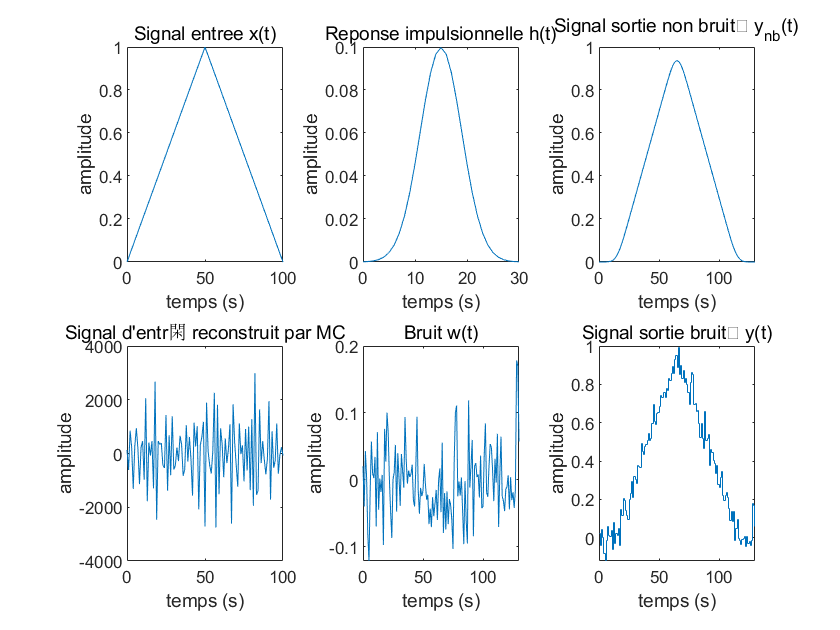

subplot(2,3,5)
plot(t,w); 
xlabel('temps (s)'); ylabel('amplitude'); title('Bruit w(t)');

%**************************************************************************
% 7. D閏onvolution l2 par moindres carr閟

%--------------------------------------------------------------------------
x_rec= inv(H'*H)*H'*y;
%--------------------------------------------------------------------------

subplot(2,3,4)
plot(t_x,x_rec)
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entr閑 reconstruit par MC');

### 3. Construire la matrice carrée D1 （critere de penalisation）

% Construction de la matrice D1 de diff閞entiation
dcol_1 = zeros(1,N_x);
dcol_1(1:2) = dcol_1(1:2) + [1 -1];
dlig_1 = zeros(1,N_x);  
dlig_1(1,1) = dcol_1(1,1);
D1 = toeplitz(dcol_1,dlig_1);

### 4. Calculer la solution régularisée x（a）

% Intervalle de variation du coefficient de regularisation
min_alpha=-7;
pas_alpha=0.1;
max_alpha=+2;
i_alpha=0;

% choix "optimal" pour alpha = 0.0013, ie var_alpha=-2.9
%var_alpha=-2.9;

% ligne suivante (ainsi que "end") ? d閏ommenter pour faire varier alpha

for var_alpha=min_alpha:pas_alpha:max_alpha

alpha=10^var_alpha;
i_alpha=i_alpha+1;
%--------------------------------------------------------------------------
x_rec_l2 (:,i_alpha)= inv(H'*H + alpha * D1'*D1)*H'*y;
%--------------------------------------------------------------------------
err_rec(:,i_alpha)=x-x_rec_l2(:,i_alpha);

Werr_rec(i_alpha)=err_rec(:,i_alpha)'*err_rec(:,i_alpha);
F(i_alpha)=norm(D1*x_rec_l2 (:,i_alpha),2)^2;
G(i_alpha)=norm(y-H*x_rec_l2 (:,i_alpha),2)^2;
end

### 5. Tracer l’évolution de l’énergie de l’erreur de reconstruction en fonction dea. Ecrire une procédure permettant d’approcher la valeur optimale de a.

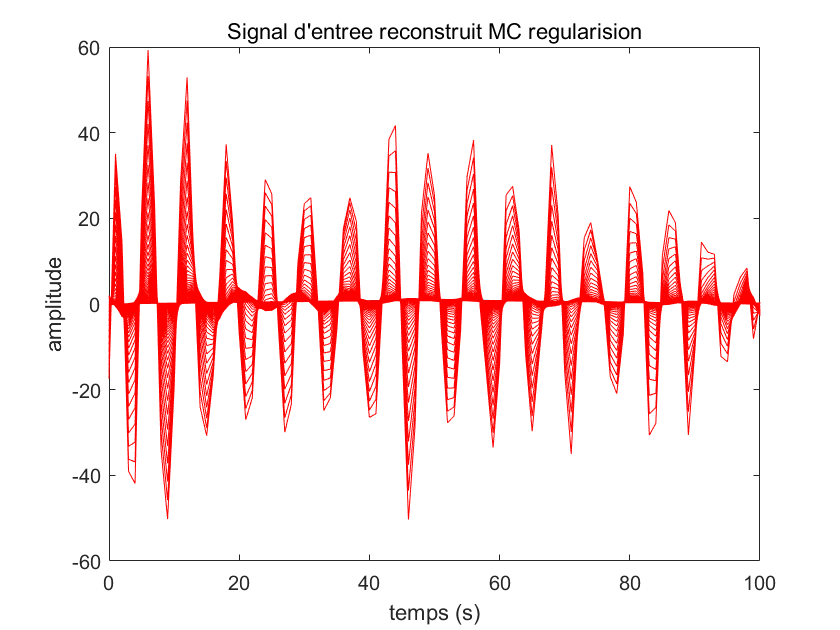

% trac� du signal reconstruit superpos� au signal recherch�
%这些courebe时对应reconstruiction par 不同的 alpha 10^（-7，2）
figure
plot(t_x,x)
hold on
plot(t_x,x_rec_l2,'r')
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entree reconstruit MC regularision');
hold off

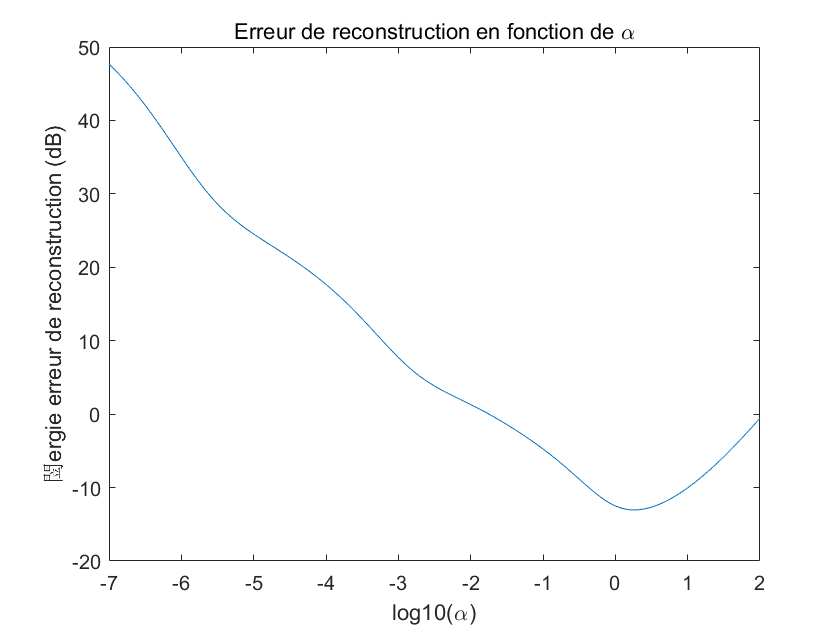


%**************************************************************************
% 閚ergie de l'erreur de reconstruction en fonction du coefficient de r間ularisation
% � d閏ommenter lorsque l'on fait varier alpha
figure
var_alpha=min_alpha:pas_alpha:max_alpha;
plot(var_alpha,10*log10(Werr_rec))
xlabel('log10(\alpha)'); ylabel('閚ergie erreur de reconstruction (dB)'); title('Erreur de reconstruction en fonction de \alpha');

%**************************************************************************
% trac� du signal reconstruit superpos� au signal recherch� pour alpha
% optimal (choix "optimal" pour alpha = 0.0013, ie var_alpha=-2.9)
[W_err_rec_min,i_alpha_opt] = min(Werr_rec);
alpha_opt=10^(min_alpha+pas_alpha*(i_alpha_opt-1))

alpha_opt = 1.9953

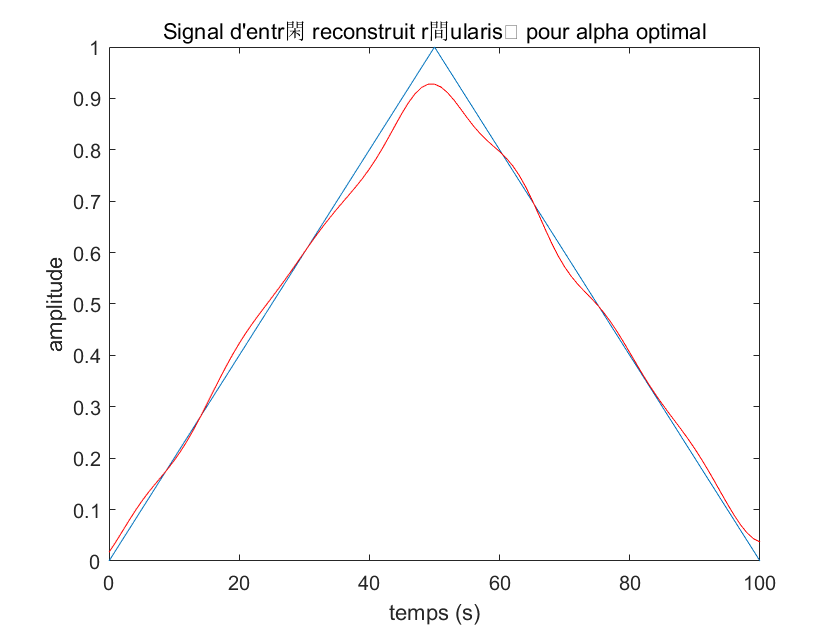

figure
plot(t_x,x)
hold on
plot(t_x,x_rec_l2(:,i_alpha_opt),'r')
xlabel('temps (s)'); ylabel('amplitude'); title('Signal d''entr閑 reconstruit r間ularis� pour alpha optimal');
hold off

6. 比较两种model of regularisation

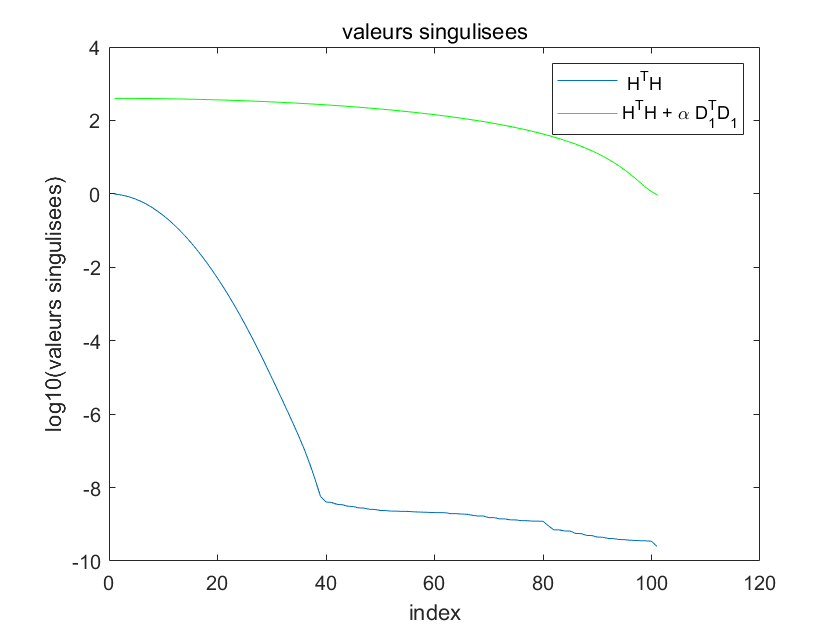

%**************************************************************************
% comparaison des conditionnements l2
figure
plot(log10(svd(H'*H)))%以降序顺序返回矩阵 A 的奇异值。
hold on
plot(log10(svd(H'*H + alpha * D1'*D1)),'g')
xlabel('index'); ylabel('log10(valeurs singulisees)'); 
title('valeurs singulisees')
legend(' H^TH','H^TH + \alpha D_1^TD_1');
hold off

display('conditionnement')

conditionnement


cond(H'*H)

ans = 3.9345e+09

max(svd(H'*H))/min(svd(H'*H)) %la matrice du critere dans cas non regulariser

ans = 3.9345e+09

cond(H'*H + alpha * D1'*D1) %dans cas regulariser

ans = 419.1022

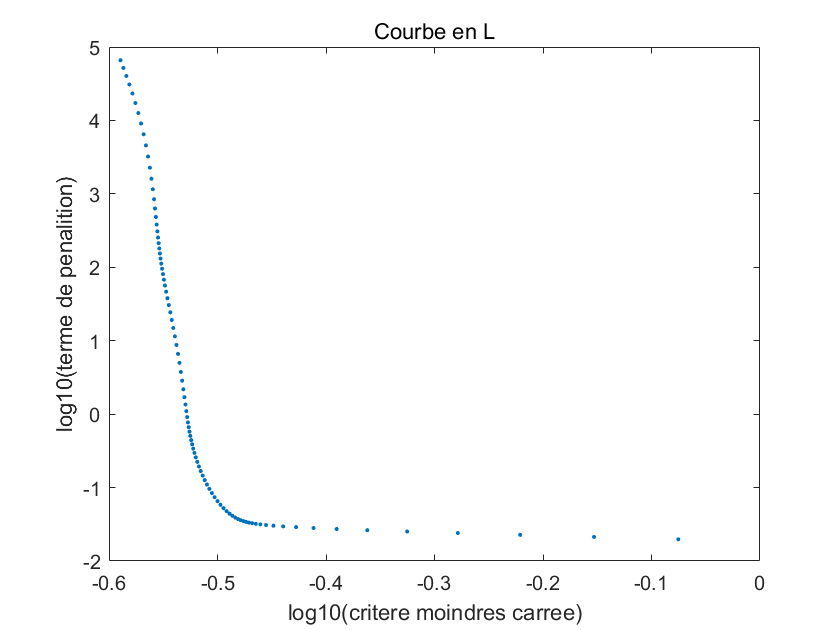

%**************************************************************************
% Courbe en L
%log estimal du penalise en fonction du log estimal du moindre carree
%permet d'avoir alpha optimal pour regler le parametre de regularisation.

figure
plot(log10(G),log10(F),'.')
xlabel('log10(critere moindres carree)'); ylabel('log10(terme de penalition)'); title('Courbe en L');

## 第三部分：analyse du conditionnement du problème（与 filtre gaussien de ecart type有关）

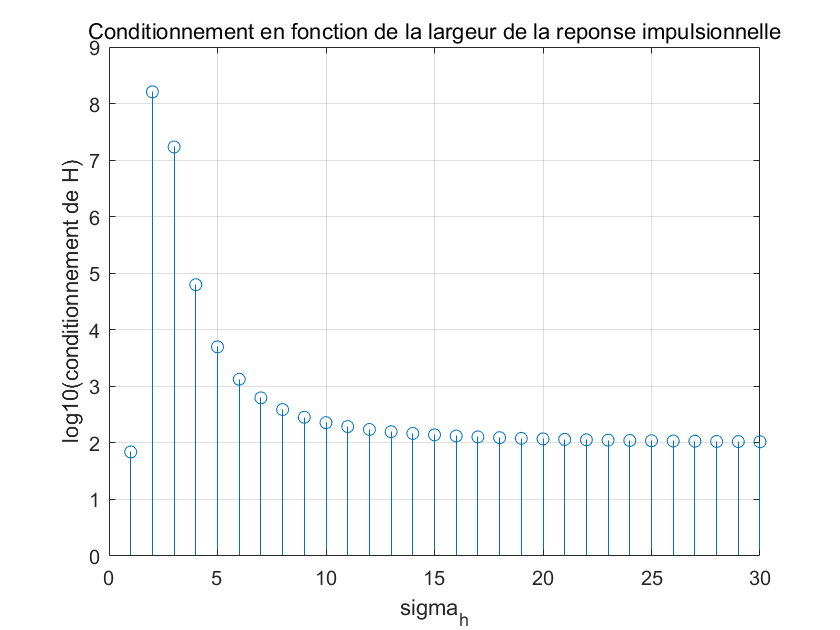

%**************************************************************************
% conditionnement en fonction de la largeur du filtre

figure
sigma=1:N_sigma;
stem(sigma,log10(cond_H)) %
grid
xlabel('sigma_h'); ylabel('log10(conditionnement de H)'); title('Conditionnement en fonction de la largeur de la reponse impulsionnelle');

%在echell log，condition tres mauvais（8） qui evolu en fonction du ecart type de la gaussienne
